# Proximal-Distal Analysis Code

Calculates the average changes in segment/sucker, sucker width and segment width down the proximal-distal axis of the arm. 

### Cassady S. Olson

Load in data and set common parameters 

clear

% Load in data
% Add data folder to path
addpath("data\")

% arm 2 data
load("Arm2_Measurement.mat");
Arm2_Measurements = Measurement;
% arm 1 data
load("Arm1_Measurement.mat")


% figure color parameters
green = [80/256, 200/256, 120/256];
pink = [255/256, 105/256, 180/256];

% Proximal - distal tag
posID = [1,2,3];
% Number of points along proximal - distal axis
numPos = 3;
posLabel = {'Proximal', 'Intermediate', 'Distal'};

## Segments/Sucker

Calculate and plot segments/sucker along the proximal-distal axis 

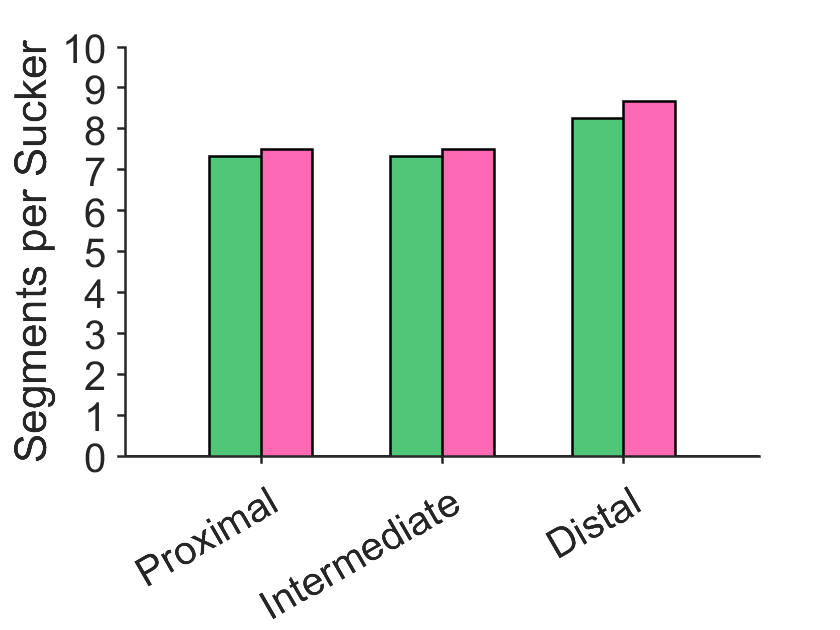

% Load seg counts
segCounts = Measurement.segCounts;
heSegCounts = Arm2_Measurements.segCounts;
avgCounts = [];
% Average across anterior and posterior 
for arm = 1:numPos
    % arm 1
    IDX = find(segCounts(:,2) == posID(arm));
    avgCounts(arm, 1) = mean(segCounts(IDX,1));

    % arm 2 
    heIDX = find(heSegCounts(:,2) == posID(arm));
    avgCounts(arm, 2) = mean(heSegCounts(heIDX,1));
    
end

% Divide by n = 6 suckers to get segment/sucker 
countPerSuck = avgCounts/6;

% Plot
figure, b = bar(flip(countPerSuck), 'LineWidth',1.3, 'BarWidth',1);

% Set plot parameters 
xticklabels(posLabel)
ylim([0, 10])
yticks([0:10])
xlim([0.25, 3.75])
ylabel('Segments per Sucker')
yticklabels(num2str((0:10)'));
b(1,1).FaceColor = green;
b(1,2).FaceColor = pink;

axis normal
ax = gca; 
ax.FontSize = 24;
ax.Box = 'off';

ax.TickDir = 'out';
ax.LineWidth = 1.3;
xticks([1,2,3])

ax.FontSize = 20;
ax.FontName = 'Helvetica';

## Sucker Width 

Calculate and plot average and SEM of sucker width along the proximal-distal axis 

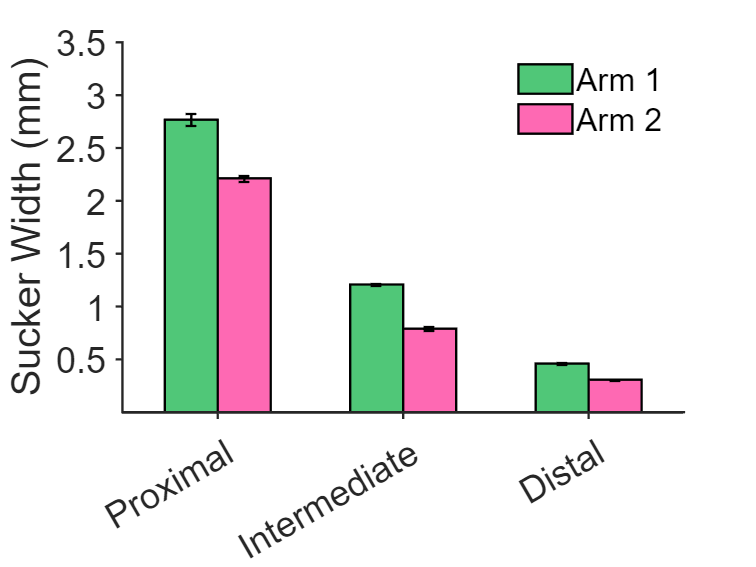

% arm 1 sucker width 
suckerWidth = Measurement.suckerWidth;
% arm 2 sucker width 
heSuckerWidth = Arm2_Measurements.suckerWidth;

avgSuckerWidth = [];
stdSuckerWidth = [];
semSuckerWidth = [];

% Find average, standard deviation and SEM 
for pos = 1:numPos
    % arm 2
    heidx = heSuckerWidth(:,2) == posID(pos);
    thisHEWidth = heSuckerWidth(heidx,1)./1000;
    avgSuckerWidth(pos, 1) = mean(thisHEWidth,1);
    stdSuckerWidth(pos, 1) = std(thisHEWidth,[],1);
    semSuckerWidth(pos, 1) = std(thisHEWidth,[],1)./sqrt(length(heidx));
    
    %arm 1
    idx = suckerWidth(:,2) == posID(pos);
    thisWidth = suckerWidth(idx,1)./1000;
    avgSuckerWidth(pos, 2) = mean(thisWidth,1);
    stdSuckerWidth(pos, 2) = std(thisWidth,[],1);
    semSuckerWidth(pos, 2) = std(thisWidth,[],1)./sqrt(length(idx));
    

end


% Plot 
figure,
b = bar(flip(flip(avgSuckerWidth,2), 1), 'LineWidth',1.3, "BarWidth",1); 
hold on

[ngroups,nbars] = size(avgSuckerWidth);

for i = 1:nbars
    x(i, :) = b(i).XEndPoints;
end

er = errorbar(x',flip(flip(avgSuckerWidth,2)), flip(flip(semSuckerWidth,2)), 'LineStyle','none', 'Color', 'k', 'LineWidth', 1.3);                               

% Set plot parameters 
b(1,1).FaceColor = green;
b(1,2).FaceColor = pink;
xticklabels((posLabel))
ylabel('Sucker Width (mm)')
axis normal
ax = gca; 
ax.FontSize = 20;
ax.FontName = 'Helvetica';
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 1.3;
xticks([1,2,3])
ylim([0,3.5])
yticks([0.5:0.5:3.5])
legend('Arm 1', 'Arm 2', 'Location', 'northeast', 'TextColor', 'k')
legend('boxoff')

## Segment Width 

Calculate the total average and SEM of segments down the proximal-distal average 

% arm 1 segments
segWidth = Measurement.segWidth; 
% arm 2 segments 
heSegWidth = Arm2_Measurements.segWidth;

avgWidth = [];
semWidth = [];

for n = 1:numPos
    %arm 2
    heboth = find(heSegWidth(:, 2) == n);
    avgWidth(n, 1) = mean(heSegWidth(heboth, 1));
    semWidth(n, 1) = std(heSegWidth(heboth, 1))./sqrt(length(heSegWidth(heboth,1)));

    %arm 1
    both = find(segWidth(:, 2) == n);
    avgWidth(n, 2) = mean(segWidth(both, 1));
    semWidth(n, 2) = std(segWidth(both, 1))./sqrt(length(segWidth(both,1)));

end


Run stats to compute significance (p < 0.05) along the proximal-distal axis 

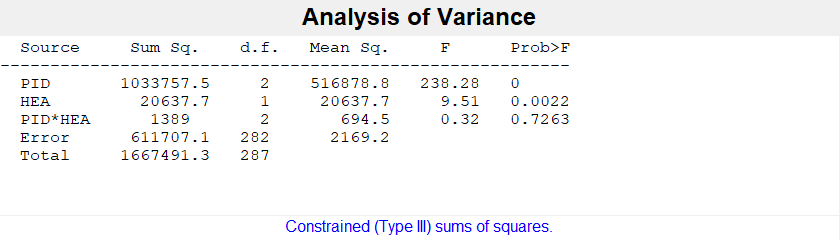

% Combine both series into one
totalWidth = zeros(288, 3); 
totalWidth(:,1:2) = [segWidth(:,1:2); heSegWidth(:,1:2)];
totalWidth(:, 3) = [ones([144,1]); 2*ones([144,1])]; 

% Run anova
[p, table, stats] = anovan(totalWidth(:,1), {totalWidth(:,2), totalWidth(:,3)},'model', 'interaction','varnames', {'PID', 'HEA'});

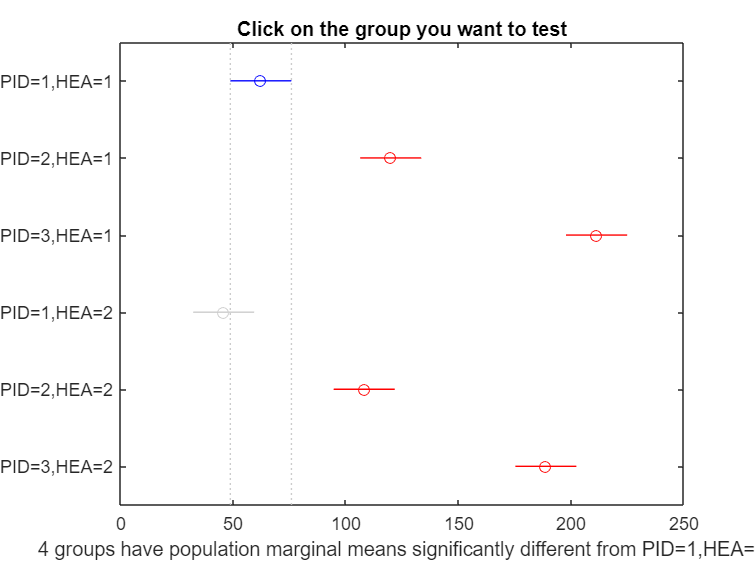

% Run post test
[c, ~, h] = multcompare(stats, "Dimension",[1,2]);

Generate plot with significance stars 

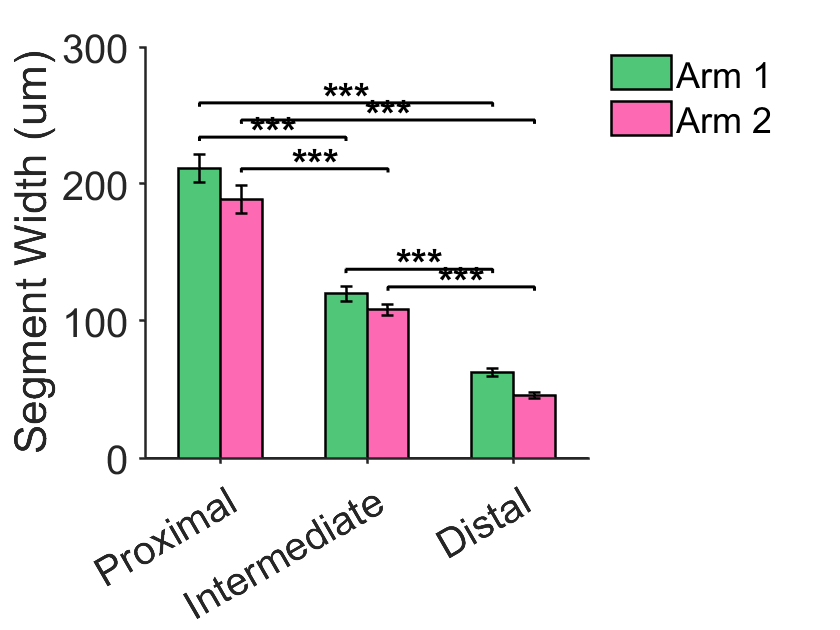

clear y 

% Plot with stars
figure,
b = bar(flip(flip(avgWidth,2)), 'LineWidth',1.3, 'BarWidth', 1); 
hold on

[ngroups,nbars] = size(avgWidth);

% Get the x coordinate of the bars
for i = 1:nbars
    y(i,:) = b(i).XEndPoints;
end
y = y';

% add errorbar
er = errorbar(y,flip(flip(avgWidth,2)), flip(flip(semWidth,2)), 'LineStyle','none', 'Color', 'k', 'LineWidth', 1.3);   

% Use sigstar to add stars 
% select significance values for relavent groups 
comp = [1,3; 2, 4; 3, 5; 4, 6; 1, 5; 2, 6];
for get = 1:length(comp)
    indx = find(comp(get, 1) == c(:, 1) & comp(get, 2) == c(:,2));
    pVal1(get) = c(indx, end); 
end

% comparison groups as x coordinate of bars
group = {[y(2,2), y(3,2)], [y(2,1), y(3,1)], [y(1,2), y(2,2)], [y(1,1), y(2,1)], [y(1,2), y(3,2)], [y(1,1), y(3,1)]}; 

% add stars
d = sigstar(group, pVal1);
set(d(:,2),'FontSize',20, 'FontWeight', 'bold', 'Color', 'k')


% Set plot parameters 
b(1,1).FaceColor = green;

b(1,2).FaceColor = pink;

xticklabels((posLabel))
ylabel('Segment Width (um)')
axis normal
ax = gca; 
ax.FontSize = 24;
ax.Box = 'off';
ax.TickDir = 'out';
ax.LineWidth = 1.3;
xticks([1,2,3])
ax.FontSize = 20;
ax.FontName = 'Helvetica';
ylim([0,300])
legend('Arm 1', 'Arm 2', 'Location', 'northeastoutside', 'TextColor', 'k')
legend('boxoff')